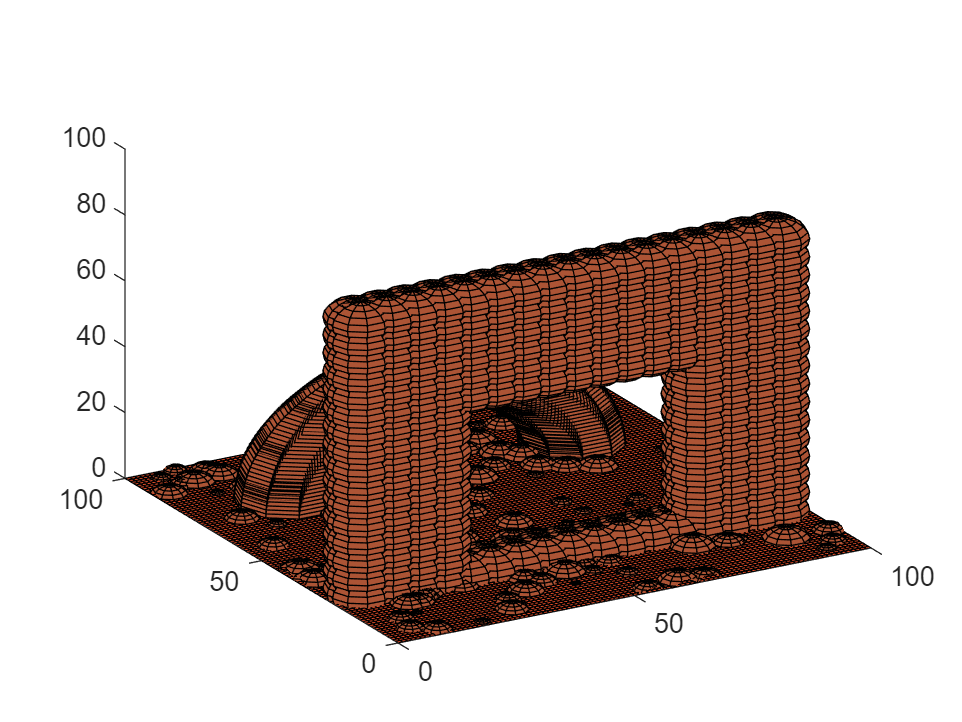

% Create a new world and add obstacles to it 
space = world(100, 100, 100, Obstacle.empty);
space = add_arch(space, [50 75 0], 30, 80, 10);
space = add_terrain(space, 150, 3);
%space = add_wall(space, 20, 80, 40, 50, -10, 15, 6);
space = add_holy_wall(space, 0, 100, 20, 30, -10, 90, 6, [50 20 30], 25);
plot_world(space);


% Define the Helicopter dimension as a min clearance from obstacle
clearance = 10;

% Create a PRM planner over the space for the helicopter
planner = PRM(200, 10, space, clearance);
start = [45 1 70];
goal = [95 95 20];

% Now try an adaptive sampler
min_std = 5;
delta = (max([space.xmax space.ymax space.zmax]))/30;
path_found = false;
counter = 0

counter = 0

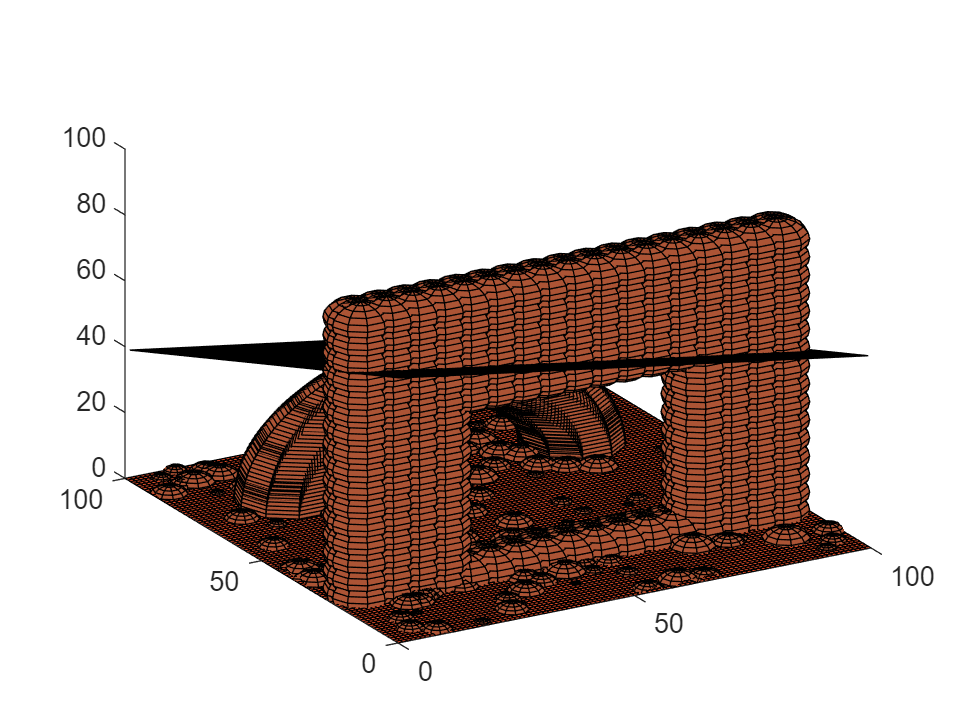

Chosen std dev: 8.3333


Number of iterations: 2


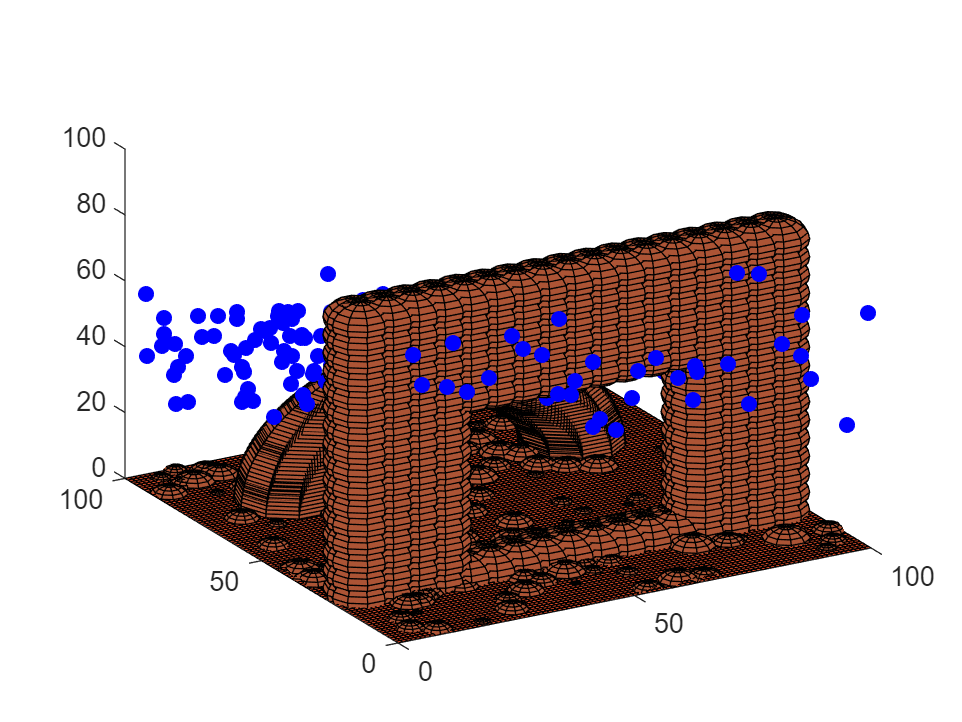

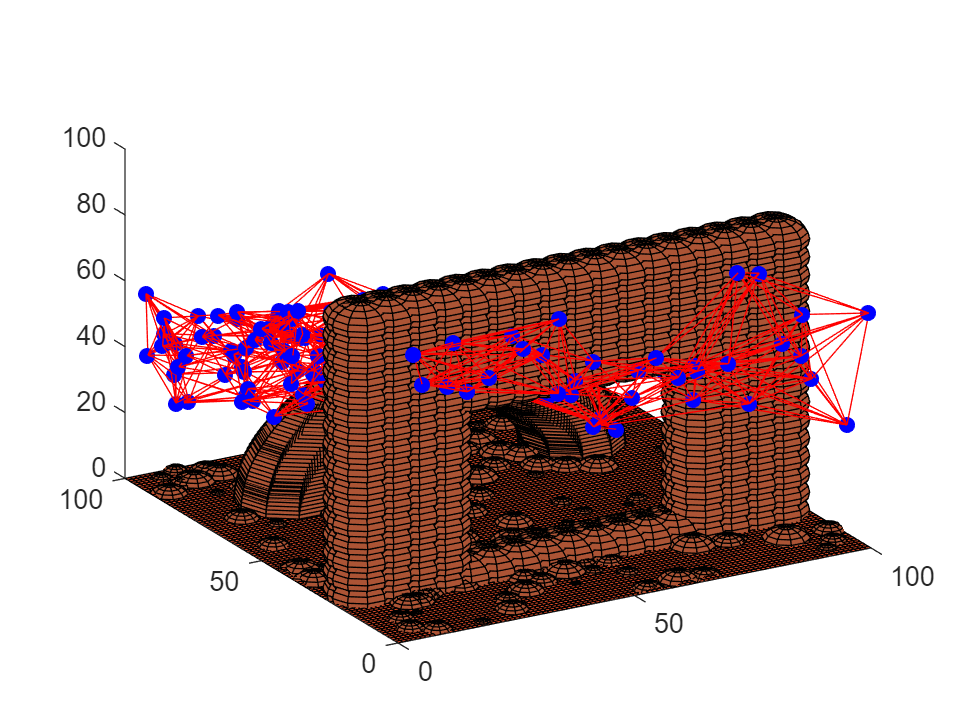

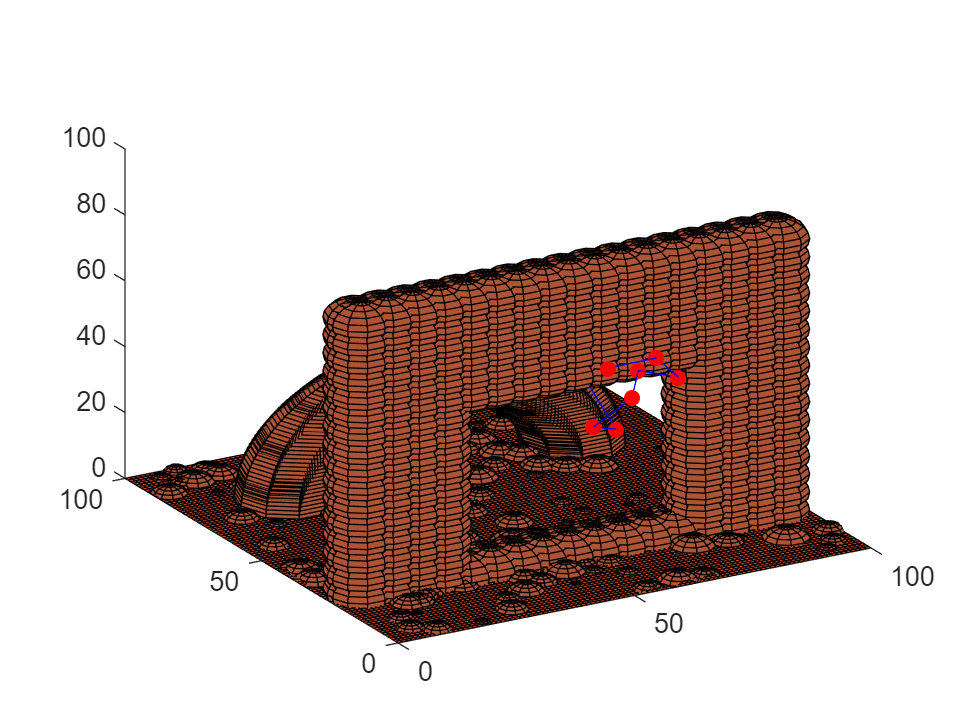

while path_found == false
    counter = counter + 1;
    a_sampled = adaptive_sampler(planner, start, goal, min_std);
    
    % Connect up the graph
    a_sampled = create_edges(a_sampled);

    try
        mapped = find_path(a_sampled, start, goal);
    catch
        min_std = min_std + delta;
        continue
    end

    path_found = true;
    disp(['Chosen std dev: ', num2str(min_std)]);
    disp(['Number of iterations: ', num2str(counter)]);
    show_sample(a_sampled);
    show_graph(a_sampled);
    show_path(mapped);
end

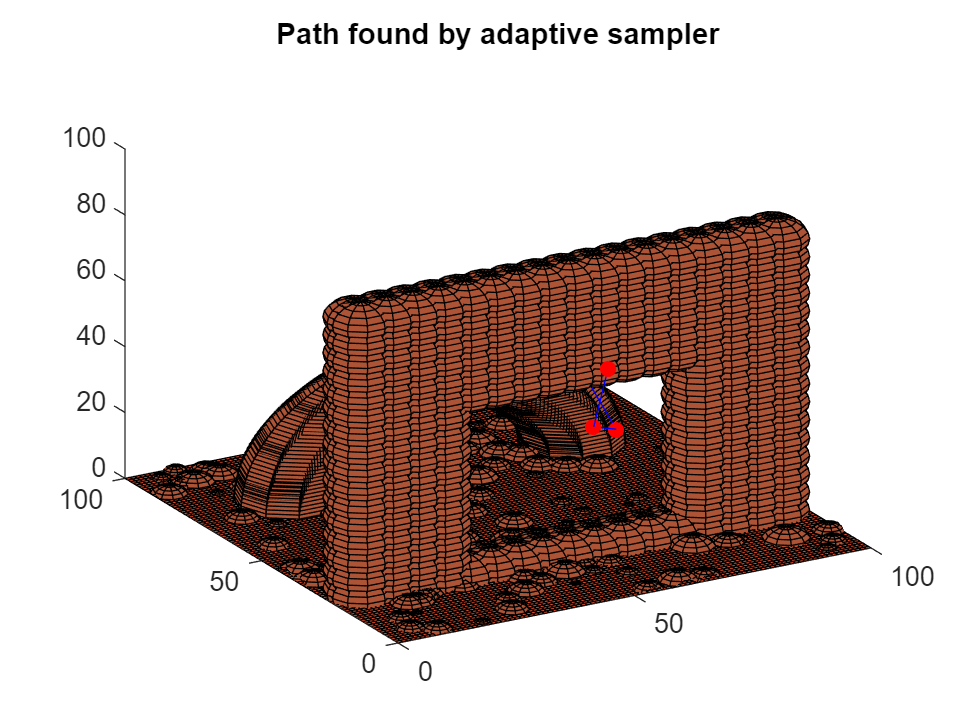


% Perform post-processing
mapped = post_process(mapped);
show_path(mapped);
title('Path found by adaptive sampler')


% Try smoothing
mapped = smooth_path(mapped);
show_smooth(mapped);

Path length from numerical integration: 130.7379


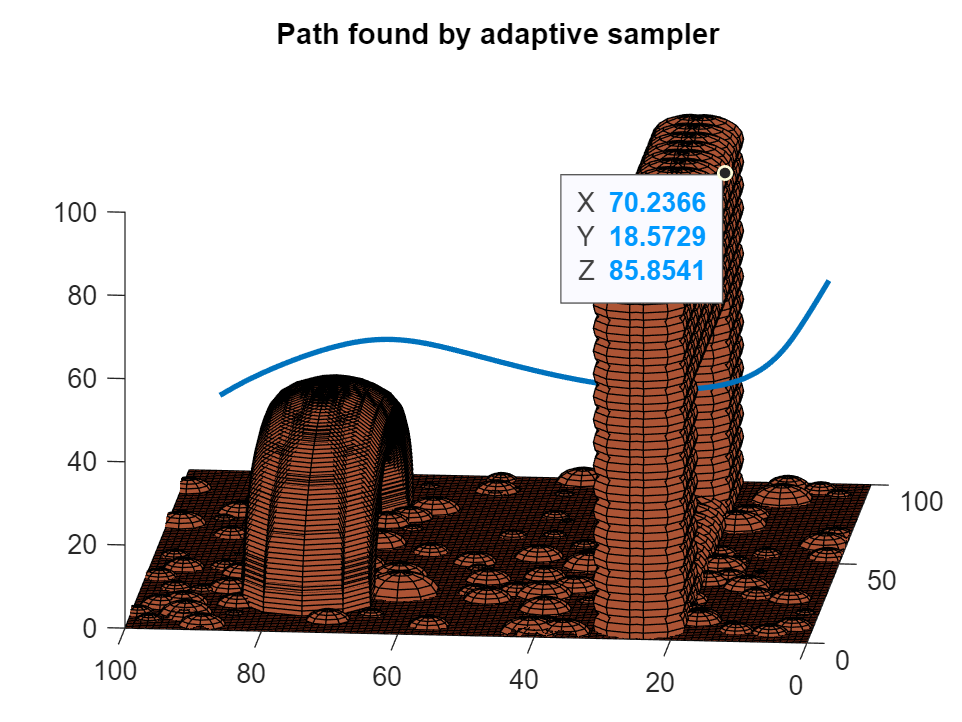

title('Path found by adaptive sampler')